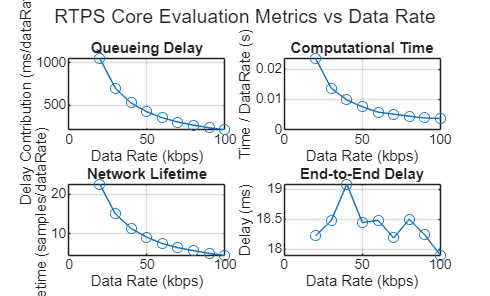

% Updated RTPS
% saves all metrics as .csv files to:
%   C:\Users\saidu\Documents\MATLAB
%
clc; clear;

%% Output Directory
outDir = 'C:\Users\saidu\Documents\MATLAB';
if ~exist(outDir,'dir')
    mkdir(outDir);
end

%% Network Parameters
areaSize = 200; % cm (2m x 2m)
numRelays = 12;
numSources = 8;
numSink = 1;
numNodes = numRelays + numSources + numSink;
range = 50; % cm communication range
initialEnergy = 50; % Joules initial energy per node
energyThreshold = 0.2 * initialEnergy; % death threshold (20%)
packetSize = 1500; % bytes per packet
dataRates = 20:10:100; % kbps
simTime = 1000; % a reference duration (not directly consumed in loop)
queueDelayBase = 5; % ms base queueing delay contribution
queueVar = 10; % ms variation added to normal data delay

%% Node Initialization
roles = [repmat("Relay", 1, numRelays), repmat("Source", 1, numSources), "Sink"];
positions = rand(numNodes, 2) * areaSize;
energyOriginal = initialEnergy * ones(numNodes, 1);
sinkID = numNodes;

%% Import Sensor Data
sensorData = readmatrix('DATA.csv');
if size(sensorData,2) < 5
    error('Expected at least 5 columns of sensor data (HR,BP,BT,RR,BS).');
end
if numSources ~= 8
    warning('Code assumes 8 sources in criticality logic.');
end

numSamples = size(sensorData,1); % number of time samples in DATA.csv

%% Metrics Initialization
% metrics columns:
% 1 QueueDelay
% 2 CompTime
% 3 Lifetime
% 4 EndToEndDelay
% 5 Throughput
% 6 RoutingOverhead
% 7 Jitter
metrics = zeros(length(dataRates), 7);

% energy per source node (consumed energy)
energyPerSource = zeros(length(dataRates), numSources);

%% Simulation Loop Across Data Rates
for drIdx = 1:length(dataRates)
    dataRate = dataRates(drIdx);

    % Reset dynamic state for this data rate
    energy = energyOriginal;
    nodeDead = false(numNodes, 1);

    totalQueueDelay = 0;

    % per-sample E2E mean delay
    totalE2EDelay = zeros(numSamples, 1);

    % network lifetime tracker
    networkLifetime = 0;

    % jitter / throughput / overhead tracking
    allPacketDelays = [];        % store delay (ms) of every successfully delivered packet
    deliveredPackets = 0;        % count of all successfully delivered packets
    relayPackets = 0;            % count of packets that used relay forwarding (normal traffic path)

    % timing for computational time
    tStart = tic;

    % Optional: dynamic queue fluctuation profile
    queueFluctuation = 1 + 0.3 * sin(1:numSamples); %#ok<NASGU>

    % Iterate over each sensor sample (treated as a "round")
    for t = 1:numSamples
        roundE2EDelay = 0;
        validCount = 0;

        % Each source attempts to transmit its data
        for s = 1:numSources
            srcID = numRelays + s;
            if nodeDead(srcID)
                continue;
            end

            % ---------------------------
            % Extract physiological readings for this time sample
            HR = sensorData(t,1); % Heart Rate
            BP = sensorData(t,2); % Blood Pressure proxy
            BT = sensorData(t,3); % Body Temperature
            RR = sensorData(t,4); % Respiration Rate
            BS = sensorData(t,5); % Blood Sugar / Glucose

            % ---------------------------
            % Determine if data is critical for this source
            switch s
                case 1
                    isCritical = (HR < 50 || HR > 120);
                case 2
                    isCritical = (BP >= 180 || BP <= 90);
                case 3
                    isCritical = (BT >= 40 || BT < 35);
                case 4
                    isCritical = (RR < 8 || RR > 30);
                case 5
                    isCritical = (BS < 54 || BS >= 300);
                otherwise
                    isCritical = false;
            end

            % Binary data marking (OLQS-style)
            if isCritical
                binaryData = [0 1]; %#ok<NASGU> % Critical data
            else
                binaryData = [0 0]; %#ok<NASGU> % Normal data
            end

            % ---------------------------
            % Routing logic
            if isCritical
                % Priority: direct transmission to sink
                distToSink = norm(positions(srcID,:) - positions(sinkID,:));

                % Delay model for direct emergency transmission
                delay_direct_random = rand() * 100;           % ms random emergency delay
                delay_direct_propag = distToSink * 0.1;        % ms distance-related delay
                delay = delay_direct_random + delay_direct_propag;

                % Record delay contribution
                roundE2EDelay = roundE2EDelay + delay;

                % Energy consumption for direct emergency transmission
                energy(srcID) = energy(srcID) - 0.1;

                % Packet accounting
                deliveredPackets = deliveredPackets + 1;
                allPacketDelays(end+1,1) = delay; %#ok<SAGROW>

                % Node death check for source
                if energy(srcID) < energyThreshold
                    nodeDead(srcID) = true;
                end

            else
                % Non-critical / normal data
                % Find all eligible relay nodes within range
                dists = vecnorm(positions - positions(srcID,:), 2, 2);
                eligible = find(dists <= range & roles == "Relay" & ~nodeDead);

                if isempty(eligible)
                    % no successful forwarding, skip this source
                    continue;
                end

                % Compute QoS metrics for each eligible relay
                DelayAll = rand(length(eligible),1)*100;          % ms hop delay
                SINR = 10 + rand(length(eligible),1)*5;           % dB-ish
                SNR = SINR + rand(length(eligible),1)*5;          % dB-ish
                interferenceRatio = SINR ./ SNR;
                LQI = interferenceRatio + DelayAll;               % link quality indicator

                % RLTD-style partial cost using LQI and Delay
                RLTD_Cost_Sub = 0.5 * LQI + 0.5 * DelayAll;

                % Select best relay with minimum cost
                [~, bestIdx] = min(RLTD_Cost_Sub);
                nextHop = eligible(bestIdx);

                % Safety guard
                if nextHop > length(energy)
                    continue;
                end

                % Delay model for relay forwarding
                perHopDelay = DelayAll(bestIdx) + rand()*queueVar;
                delay = perHopDelay;

                % Add this packet delay to round stats
                roundE2EDelay = roundE2EDelay + delay;

                % Energy cost for source and relay
                energy(srcID) = energy(srcID) - 0.05;
                energy(nextHop) = energy(nextHop) - 0.05;

                % Packet accounting
                deliveredPackets = deliveredPackets + 1;
                relayPackets = relayPackets + 1;
                allPacketDelays(end+1,1) = delay; %#ok<SAGROW>

                % Death checks
                if energy(srcID) < energyThreshold
                    nodeDead(srcID) = true;
                end
                if energy(nextHop) < energyThreshold
                    nodeDead(nextHop) = true;
                end
            end
            % ---------------------------

            % Check network lifetime: first time any node drops below threshold
            if networkLifetime == 0 && any(energy < energyThreshold)
                networkLifetime = t;
            end

            % Queueing delay accumulation
            totalQueueDelay = totalQueueDelay + queueDelayBase;

            % Count valid transmission for E2E averaging
            validCount = validCount + 1;
        end % end for each source s

        % Store average E2E delay for this timeslot t
        if validCount > 0
            totalE2EDelay(t) = roundE2EDelay / validCount;
        else
            totalE2EDelay(t) = NaN;
        end
    end % end for each time sample t

    % ---------------------------
    % Computational time (normalized by data rate)
    tComp = toc(tStart) / dataRate;

    % ---------------------------
    % Throughput calculation
    % deliveredPackets = number of packets that actually made an attempt
    % For throughput in Mbps:
    % bitsDelivered = deliveredPackets * packetSize * 8
    % durationSeconds approximated as numSamples (1 "round" ~ 1s logical sampling interval)
    bitsDelivered = deliveredPackets * packetSize * 8;
    durationSeconds = numSamples;
    throughput_Mbps = (bitsDelivered / durationSeconds) / 1e6;

    % ---------------------------
    % Routing Overhead calculation
    % Define overhead as fraction of packets that required relay forwarding
    % relayPackets counts normal packets sent via intermediate relay
    % deliveredPackets counts all packets successfully handled
    if deliveredPackets > 0
        routingOverheadRatio = relayPackets / deliveredPackets;
    else
        routingOverheadRatio = 0;
    end

    % ---------------------------
    % Jitter calculation
    % Classic jitter proxy: stdev of inter-arrival delay differences
    % We use the per-packet delays captured in allPacketDelays (ms)
    % jitter = std( diff(packetDelayList) )
    if length(allPacketDelays) >= 2
        interDelayDiffs = diff(allPacketDelays); % ms difference between consecutive packet delays
        jitter_ms = std(interDelayDiffs);
    else
        jitter_ms = 0;
    end

    % ---------------------------
    % Aggregate Metrics for this data rate
    avgValidE2EDelay = mean(totalE2EDelay(~isnan(totalE2EDelay)));

    metrics(drIdx,1) = totalQueueDelay / dataRate;        % Queueing Delay metric
    metrics(drIdx,2) = tComp;                             % Computational Time metric
    metrics(drIdx,3) = networkLifetime / dataRate;        % Network Lifetime metric
    metrics(drIdx,4) = avgValidE2EDelay;                  % End-to-End Delay metric
    metrics(drIdx,5) = throughput_Mbps;                   % Throughput (Mbps)
    metrics(drIdx,6) = routingOverheadRatio;              % Routing Overhead (ratio)
    metrics(drIdx,7) = jitter_ms;                         % Jitter (ms)

    % Track per-source energy consumption
    for s = 1:numSources
        srcID = numRelays + s;
        if srcID <= length(energy)
            energyPerSource(drIdx,s) = initialEnergy - energy(srcID);
        end
    end
end

%% Save Metrics to CSV in the specified directory
% Core metrics
writematrix([dataRates(:), metrics(:,1)], fullfile(outDir,'Queueing_Delay_RTPS.csv'));           % ms/dataRate
writematrix([dataRates(:), metrics(:,2)], fullfile(outDir,'Computational_Time_RTPS.csv'));       % s/dataRate
writematrix([dataRates(:), metrics(:,3)], fullfile(outDir,'Network_Lifetime_RTPS.csv'));         % samples/dataRate
writematrix([dataRates(:), metrics(:,4)], fullfile(outDir,'End_to_End_Delay_RTPS.csv'));         % ms

% Energy per source (J consumed per source node)
writematrix(energyPerSource, fullfile(outDir,'Energy_Source_Node_RTPS.csv'));

% Additional/new metrics
writematrix([dataRates(:), metrics(:,5)], fullfile(outDir,'Throughput_RTPS.csv'));               % Mbps
writematrix([dataRates(:), metrics(:,6)], fullfile(outDir,'Routing_Overhead_RTPS.csv'));         % ratio (0-1)
writematrix([dataRates(:), metrics(:,7)], fullfile(outDir,'Jitter_RTPS.csv'));                   % ms

%% Plot Results (Core Performance)
figure;
subplot(2,2,1);
plot(dataRates, metrics(:,1), '-o');
title('Queueing Delay');
xlabel('Data Rate (kbps)');
ylabel('Delay Contribution (ms/dataRate)');
grid on;

subplot(2,2,2);
plot(dataRates, metrics(:,2), '-o');
title('Computational Time');
xlabel('Data Rate (kbps)');
ylabel('Time / DataRate (s)');
grid on;

subplot(2,2,3);
plot(dataRates, metrics(:,3), '-o');
title('Network Lifetime');
xlabel('Data Rate (kbps)');
ylabel('Lifetime (samples/dataRate)');
grid on;

subplot(2,2,4);
plot(dataRates, metrics(:,4), '-o');
title('End-to-End Delay');
xlabel('Data Rate (kbps)');
ylabel('Delay (ms)');
grid on;

sgtitle('RTPS Core Evaluation Metrics vs Data Rate');

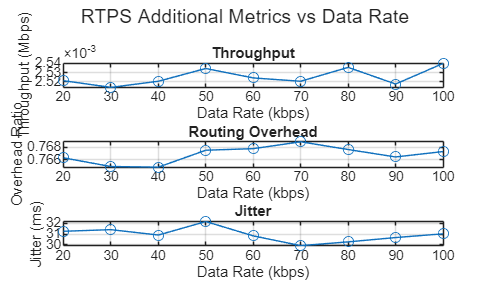


%% Plot New Metrics (Throughput, Overhead, Jitter)
figure;
subplot(3,1,1);
plot(dataRates, metrics(:,5), '-o');
title('Throughput');
xlabel('Data Rate (kbps)');
ylabel('Throughput (Mbps)');
grid on;

subplot(3,1,2);
plot(dataRates, metrics(:,6), '-o');
title('Routing Overhead');
xlabel('Data Rate (kbps)');
ylabel('Overhead Ratio');
grid on;

subplot(3,1,3);
plot(dataRates, metrics(:,7), '-o');
title('Jitter');
xlabel('Data Rate (kbps)');
ylabel('Jitter (ms)');
grid on;

sgtitle('RTPS Additional Metrics vs Data Rate');

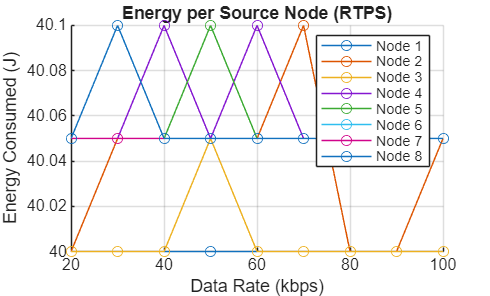


%% Plot Energy per Source Node
figure;
hold on;
for s = 1:numSources
    plot(dataRates, energyPerSource(:,s), '-o', 'DisplayName', ['Node ' num2str(s)]);
end
xlabel('Data Rate (kbps)');
ylabel('Energy Consumed (J)');
title('Energy per Source Node (RTPS)');
grid on;
legend show;
hold off;